**Initial Setup**

clear all
close all
clc

**Parameters**

base_path = '../tests/primal_test/Actual Coupling/1699207461_hard_coupling/csv/';
files = struct2table(dir(append(base_path, '*.csv')));

shape = size(files);

**Import files**

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["x", "y", "h", "p"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
for j = 1:shape(1)
    name = files.name{j};
    data(j, :, :) = table2array(readtable(append(base_path, name), opts));
end

**Plots**

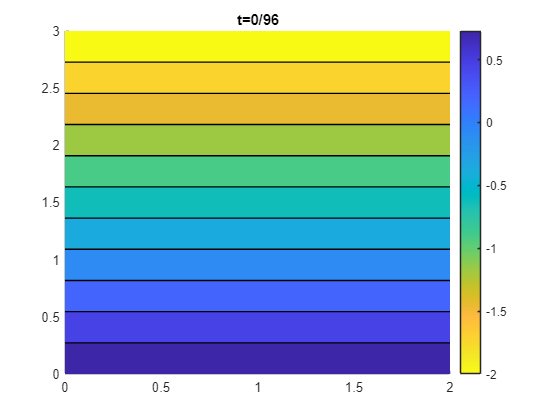

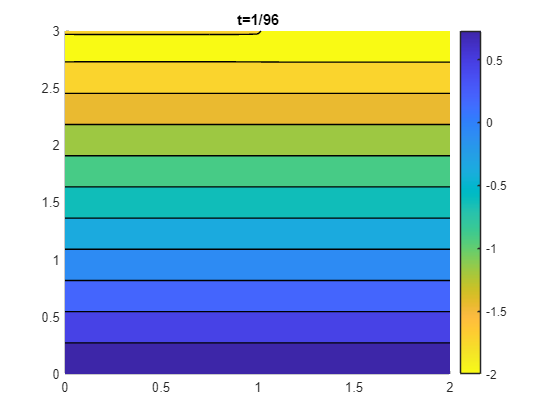

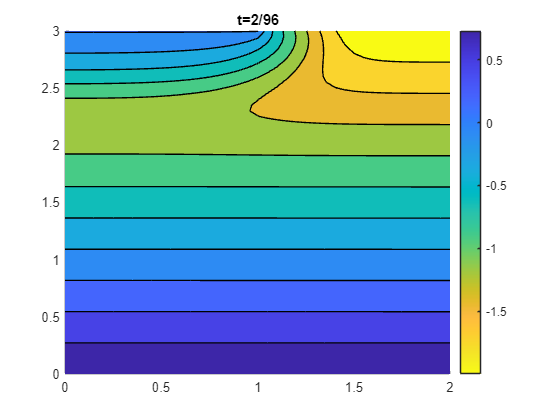

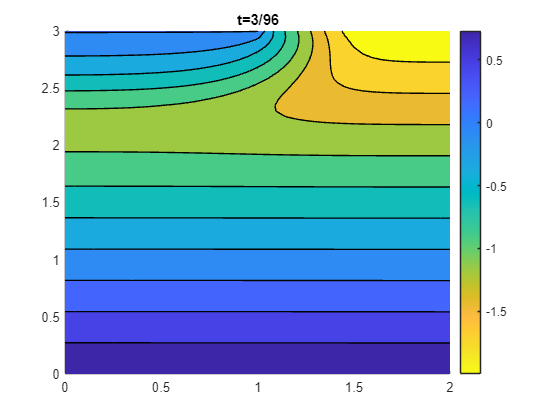

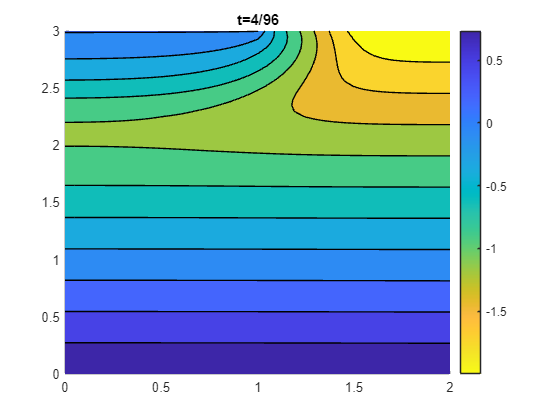

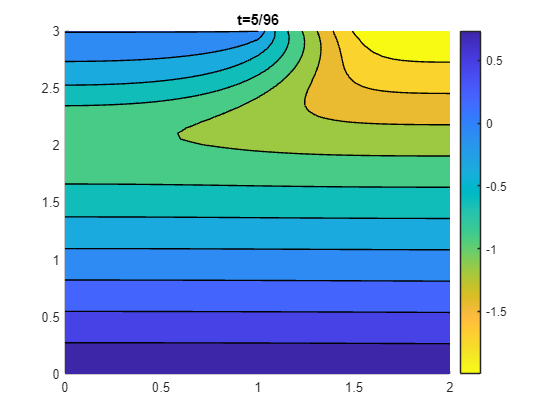

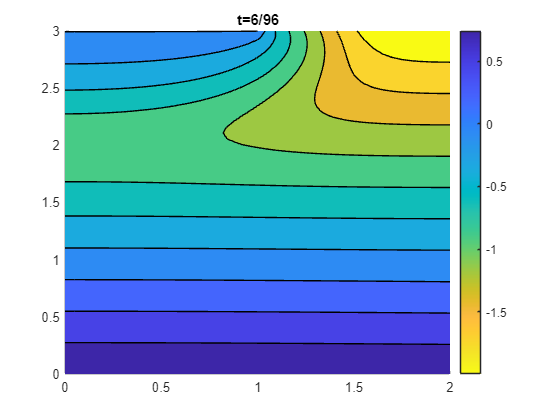

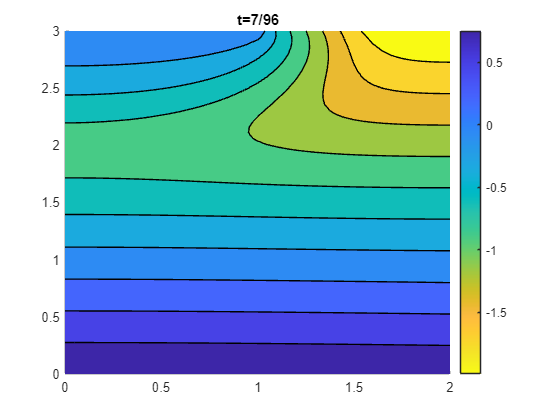

tmp = size( data(end, :, 1) );
N = (sqrt(25 + 24 * (tmp(2) - 1)) - 5) / 12;

for j = 1:shape(1)
    xq = reshape(data(j, :, 1), [2*N+1, 3*N+1]);
    yq = reshape(data(j, :, 2), [2*N+1, 3*N+1]);
    zq = reshape(data(j, :, 4), [2*N+1, 3*N+1]);

    figure
    hold on
    contourf(xq,yq,zq, 10)
    title(append('t=', append(string(j-1), '/96')))
    colormap(flipud(parula))
    colorbar
    hold off
end